## IV Praktikum 2022

### Vorbereitungsteil:

#### Aufgabe 1


$$|E| = \frac{1}{\sqrt2} 1V,
 $$
 
$$R_1=R_2=R=50 \Omega$$


#### 1. Bestimmen Sie Pmax. 

 
$$P_{max} = \frac{|E|^2}{4R}$$
    


$$|E|^2 = \left( \frac{1V} {\sqrt{2}} \right)^2$$
 
$$ \Rightarrow  $$
   
$$|E|^2 = \frac{1}{2}V^2
$$


$P_{max} = \frac{\frac{1V^2}{2}}{4R} = \frac{1V^2}{8R} = \frac 1 {400}  \frac {V^2} \Omega
$ $=2,5
$mW  

syms R E
P_max = abs(E)^2/(4*R)

$$P\_max = \frac{{\left|\text{E}\right|}^{2}}{4\,R}$$

P_max = double(subs(P_max,[E,R],[1/sqrt(2),50]))*1000  %W --> mW

P_max = 2.5000

#### 2. Bestimmen Sie S21(jω).


$$S_{21} = k \frac {U_2} E = 2 \sqrt \frac{R_1} {R_2} \frac {U_2} {U_1} \frac{U_1} {E}$$
  
$$\Rightarrow$$
 
$$S_{21} = 2 \frac {U_2} E$$



$$U_2 = I * \left( R_2+ \frac 1 {j\omega C} \right)^{-1} \\
I = \frac E {R_{ges}}$$
  
$$\Rightarrow$$
 
$$U_2 = \frac E {R_{ges}} * \left( R_2+ \frac 1 {j\omega C} \right)^{-1} \rightarrow  S_{21} = 2 \frac { \left( R_2+ \frac 1 {j\omega C} \right)^{-1}} {R_{ges}}$$



$$R_{ges} =  R + C||R \\
C||R = \frac1 {j \omega C+\frac 1 R}$$
        
$$\Rightarrow
$$
     
$$R_{ges} = R + \frac 1 {j \omega C + \frac 1 R}$$
  


$$S_{21} = 2 \frac { \left( \frac 1 R+ j\omega C \right)^{-1}} {R+ \frac R {j \omega C R + 1}} $$


syms R omega C real
R_ges = R + 1/(1i*omega*C+1/R);
S_21 = 2*((1/R+1i*omega*C)^-1)/(R+R/(1+1i*omega*C*R)) %2*R/R_ges

$$S\_21 = \frac{2}{\left(\frac{1}{R}+C\,\omega \,\mathrm{i}\right)\,\left(R+\frac{R}{1+C\,R\,\omega \,\mathrm{i}}\right)}$$

simplify(S_21,"Steps",640)

$$ans = \frac{2}{2+C\,R\,\omega \,\mathrm{i}}$$

#### 3. Bestimmen Sie |S21(jω)|² und AdB(ω).

simplify(abs(S_21)^2,"Steps",100)

$$ans = \frac{4\,R^{2}\,{\left|C\,R\,\omega -\mathrm{i}\right|}^{2}}{{\left|C\,R\,\omega -2\,\mathrm{i}\right|}^{2}\,{\left|1+C\,R\,\omega \,\mathrm{i}\right|}^{2}\,{\left|R\right|}^{2}}$$

S21 = 4/(C^2*R^2*omega^2 + 4) - (2i*C*R*omega)/(C^2*R^2*omega^2 + 4)

$$S21 = \frac{4}{C^{2}\,R^{2}\,\omega^{2}+4}-\frac{2\,C\,R\,\omega \,\mathrm{i}}{C^{2}\,R^{2}\,\omega^{2}+4}$$

simpS21_abs_quad = (4*C^2*R^2*omega^2)/(C^2*R^2*omega^2 + 4)^2 + 16/(C^2*R^2*omega^2 + 4)^2

$$simpS21\_abs\_quad = \frac{16}{{\left(C^{2}\,R^{2}\,\omega^{2}+4\right)}^{2}}+\frac{4\,C^{2}\,R^{2}\,\omega^{2}}{{\left(C^{2}\,R^{2}\,\omega^{2}+4\right)}^{2}}$$

A_db = 10*log10((C^2*R^2*omega^2 + 4)^2/(4*C^2*R^2*omega^2+16))

$$A\_db = \frac{10\,\log\left(\frac{{\left(C^{2}\,R^{2}\,\omega^{2}+4\right)}^{2}}{4\,C^{2}\,R^{2}\,\omega^{2}+16}\right)}{\log\left(10\right)}$$

simA_db = simplify(A_db,"Steps",100)

$$simA\_db = \frac{10\,\log\left(\frac{C^{2}\,R^{2}\,\omega^{2}}{4}+1\right)}{\log\left(10\right)}$$

#### 4. Zeichnen Sie AdB(ω) qualitativ. 

syms A_dB(omega)
A_dB = symfun(simA_db,[C,R,omega])

$$A\_dB(C, R, omega) = \frac{10\,\log\left(\frac{C^{2}\,R^{2}\,\omega^{2}}{4}+1\right)}{\log\left(10\right)}$$

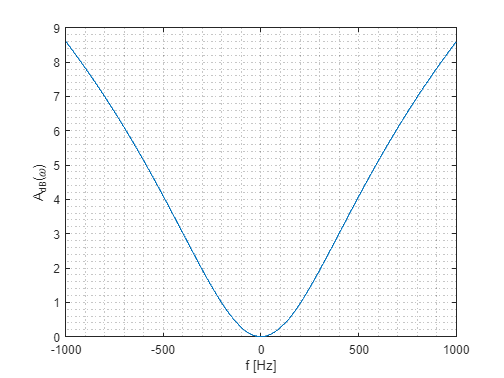

plot(-1000:1:1000,A_dB(0.1,50,-1:1/1000:1)) %Welche Werte für C?
xlabel ("f [Hz]")
ylabel("A_{dB}(\omega)")
grid("minor")

#### 5. Handelt es sich um ein Hochpass- oder ein Tiefpassfilter? Begründen Sie Ihre Antwort.

Hochpass, da tiefe Frequ. blockiert werden

wg = solve(A_db==3)

$$wg = \left(\begin{array}{c} -\frac{2\,\sqrt{10^{3/10}-1}}{C\,R}\\ \frac{2\,\sqrt{10^{3/10}-1}}{C\,R} \end{array}\right)$$

double(subs(wg,[C,R],[0.1,50]))

ans =    -0.3991
    0.3991


double(vpasolve(subs(A_dB,[C,R],[0.1,50])==3))

ans = -0.3991

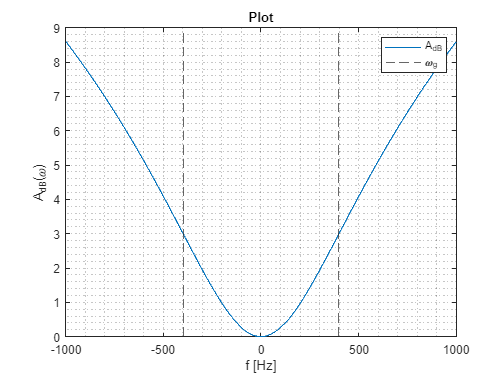

xline(ans*1000,"LineStyle","--")
xline(-ans*1000,"LineStyle","--")
xlim("auto")
ylim("auto")
legend(["A_{dB}","\omega_g"])
title("Plot")

Kondensator: $X_c = \frac 1 {j \omega C}$ mit $\omega = 2\pi f$ 


$$f_g = \frac 1 {2 \pi R C}$$


fg = 1/(1i*2*pi*R*C)

$$fg = -\frac{\mathrm{i}}{2\,C\,R\,\pi }$$

A_dB

$$A\_dB(C, R, omega) = \frac{10\,\log\left(\frac{C^{2}\,R^{2}\,\omega^{2}}{4}+1\right)}{\log\left(10\right)}$$

double(subs(A_dB,omega,2*pi*fg))

ans = -1.2494

## Aufgabe 2

- $\Omega_s < 2$  --> n=3

- 
$$\Theta = 30$$
 
$$r_1 = r_2 = 1$$
